# **Matlab案例代码解析**

## 3. 科学计算案例

### 3.4 解非线性方程

#### 3.4.1 二分法求解非线性方程

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

clear;clc;
fun = @(x) x + 6 * sin(4 * x) + 9 * cos(5 * x);
root = Bisection(fun, 3, 4, 1e-6)

root = 3.2898

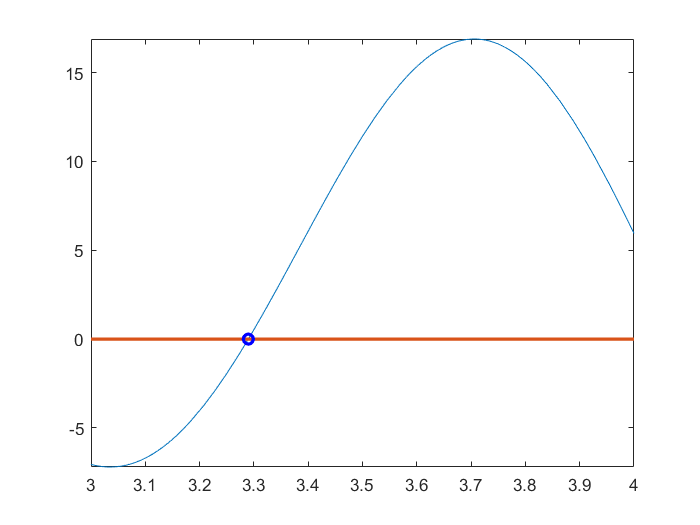

fplot(fun, [3, 4]);
hold on
plot([3, 4], [0, 0], root, fun(root), 'ob', 'LineWidth', 2);
hold off

function root = Bisection(fun, a, b, err)
%{
函数功能：二分法求解非线性方程的根；
输入：
  fun：方程句柄；
  a：搜索区间下限；
  b：搜多区间上限；
  err：精度阈值；
输出：
  root：近似解；
%} 
% = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = = 
if nargin < 4
   err = 1e-6;  % 默认精度
end
if nargin < 3
   error('输入参数不足！');
end
% 初始情况
root = NaN;   %  返回非数
if fun(a) == 0
   root = a;
end
if fun(b) == 0
   root = b;
end
if fun(a)*fun(b) > 0
   disp('两端点函数值乘积大于0，无解！');
   return;
else 
   root = FindRoot(fun, a, b, err);
end
end
function r = FindRoot(fun, a, b, err)
fa = fun(a);
x = 0.5 * (a + b);
fx = fun(x);
if fa * fx > 0                     % a 和中点之间没有根
   t = 0.5 * (a + b);
   r = FindRoot(fun, t, b, err);
else
   if fa * fx == 0
      r = 0.5 * (a + b);           % 输出根
   else
      if abs(b - a) <= err
         r = 0.25 * (b + 3 * a);
      else                         % a和中点之间有根  
         s = 0.5 * (a + b);
         r = FindRoot(fun, a, s, err);
      end
   end
end 
end